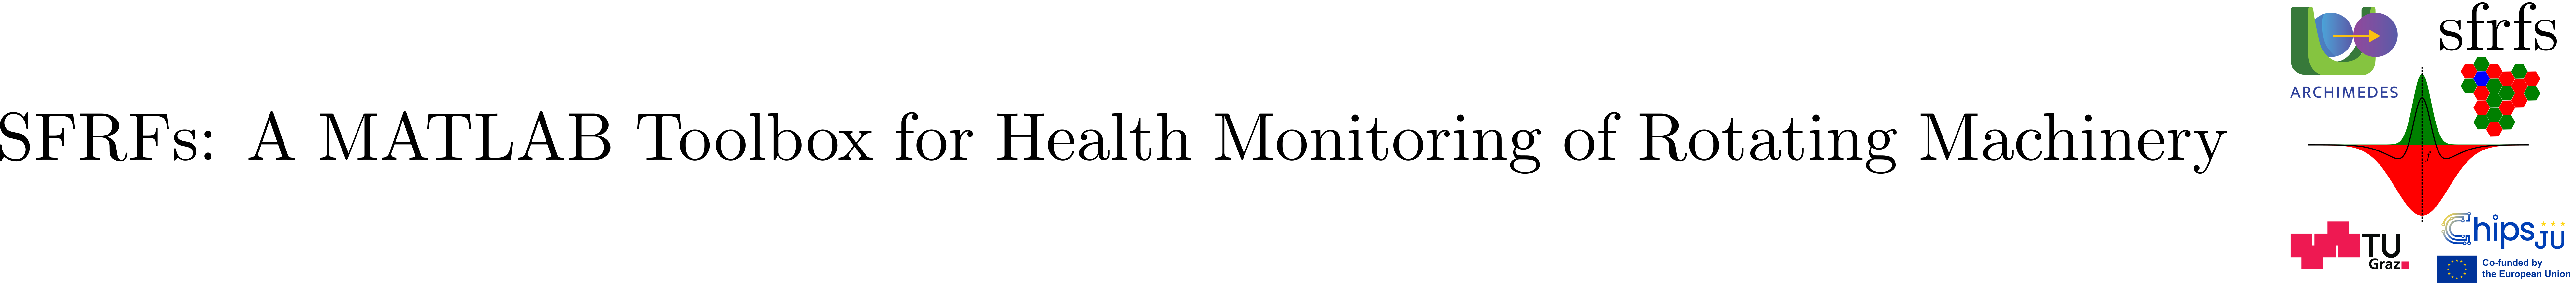

# FaultFrequencyBands

## Summary

`FaultFrequencyBands` is an abstract base class that defines a standardized structure and interface for representing characteristic fault frequency bands, independent of any specific system or component.

**Key features:**

- Abstract constant properties define fault frequency codes, fault type descriptions, group identifiers, and group-to-name mappings.

- Concrete properties store operating conditions, SFRF parameters, and a table containing computed fault frequency bands.

- Subclasses must implement the abstract `computeBands` method to generate the fault band table from the provided operating conditions.

- The resulting table includes, at minimum, the fault group, a human-readable description, speed, load, and receptive field band definitions.

- A static utility method, `extractBands`, enables consistent extraction, sorting, and structuring of band matrices from a selected table row for downstream processing.

- The class is designed to be extended by system- or component-specific implementations, for example `BearingFrequencyBands`.

This class establishes a uniform contract and shared functionality for consistent definition, computation, and handling of fault frequency bands across different powertrain components.

## Description

`FaultFrequencyBands` provides the common structure, metadata, and interfaces required by concrete implementations to compute and manage fault-related frequency bands under given operating conditions. The class is designed to support consistent handling of fault band definitions across different component types within the SFRFs framework. Figure 1 depics the class members.

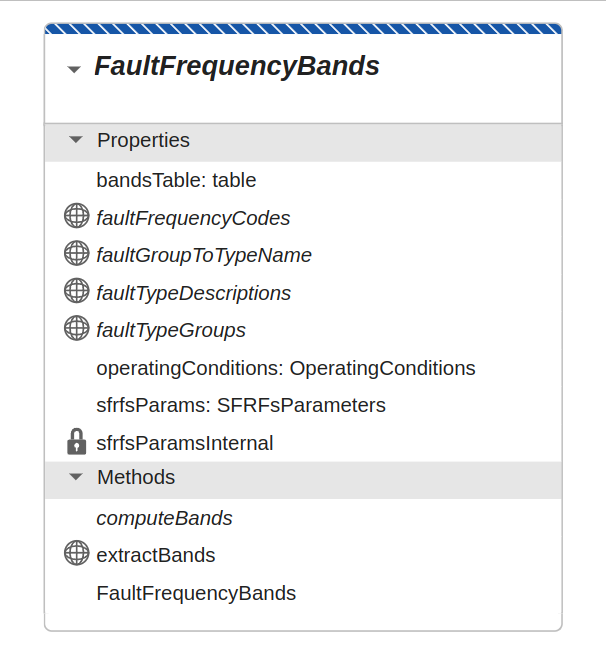

**Figure 1**. FaultFrequencyBands abstract class.

### Abstract constant properties

Subclasses must define the following constant properties:

### Concrete properties

### Abstract methods

Subclasses must implement: `computeBands``(obj, operatingConditions)` method.

This method must compute the fault frequency bands for each set of operating conditions and populate `bandsTable`. The output table contains the following columns:

- `FaultGroup`: Numeric index of the fault type

- `Description`: Human-readable fault description

- `Speed`: Shaft rotational speed (Hz)

- `Load`: Load value from `operatingConditions`

- `ReceptiveFieldBands`: Cell array of `containers.Map` elements with keys: `'Bands'` (Center and Surround ranges), `'Harmonic', 'Label', and 'Sideband'.`

### Static Utility

The class also provides a concrete static helper: `FaultFrequencyBands.extractBands``(faultBandsTable, row)`. This method extracts and lexicographically sorts the center and surround band matrices from a selected row of a fault band table. The returned structure includes frequency bounds, harmonic and sideband indices, and the characteristic frequency index, facilitating downstream processing and visualization.

### Extensibility

`FaultFrequencyBands` is intended to be subclassed by component-specific implementations, such as [`BearingFrequencyBands`](matlab:open('./BearingFrequencyBands.mlx')), which define concrete fault models and computational logic while inheriting the common interface and data layout. By providing a uniform contract, this class ensures consistency, clarity, and interoperability in the definition and handling of fault frequency bands across different powertrain components.

## API documentation

### MATLAB help

help FaultFrequencyBands

  FaultFrequencyBands Abstract frequency bands class agnostic to the
    system or component.
 
    Provides a contract for classes representing characteristic
    fault frequency bands, including common properties and abstract
    interfaces for fault type descriptions and mappings.
 
  Properties (Abstract, Constant):
    faultFrequencyCodes       - Struct or map of fault frequency codes.
    faultTypeDescriptions     - Cell array of fault type description 
                                strings.
    faultTypeGroups           - Numeric or categorical grouping of 
                                fault types.
    faultGroupToTypeName      - Inverse of faultTypeGroups
 
 
  Concrete Properties:
    operatingConditions       - OperatingConditions object
    sfrfsParams               - Parameters for SFRFs computation
    bandsTable                - Table with computed fault bands.
 
  Methods (Abstract):
    computeBands 
                              - Abstract signature 
             

### MATLAB documentation

doc FaultFrequencyBands

Opens the full class documentation in the MATLAB Help Browser, including formatted examples, links to related functions, and extended descriptions.

## Source code

The source code for the class can be found in [FaultFrequencyBands](matlab:open('../../FaultFrequencyBands.m')).

## Test

Unit test for the class is implemented in [TestFaultFrequencyBands](matlab:open('../../../tests/TestFaultFrequencyBands.m')).

% execute tests
res = runtests('Spectral Fault Receptive Fields/tests/TestFaultFrequencyBands');

Running TestFaultFrequencyBands
.....
Done TestFaultFrequencyBands
__________



% display summary of tests
SFRFsTestUtil.printTestSummary(res,80);

Test Name                                                                        | Result
-----------------------------------------------------------------------------------------
TestFaultFrequencyBands/testNormalCase                                           | Passed
TestFaultFrequencyBands/testOutOfBounds                                          | Passed
TestFaultFrequencyBands/testEmptyBands                                           | Passed
TestFaultFrequencyBands/testScalarMapIsHandled                                   | Passed
TestFaultFrequencyBands/testNestedCellIsRejected                                 | Passed



## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).